% Processed Year 1 Files 

addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')

% Casts 
cast02 = readSBScnv( 'uKN22104002_KFabcdef.cnv' );
cast03 = readSBScnv( 'uKN22104003_KFabcdef.cnv' );
cast04 = readSBScnv( 'uKN22104004_KFabcdef.cnv' );
cast05 = readSBScnv( 'uKN22104005_KFabcdef.cnv' );
cast06 = readSBScnv( 'uKN22104006_KFabcdef.cnv' );
cast07 = readSBScnv( 'uKN22104007_KFabcdef.cnv' );
cast08 = readSBScnv( 'uKN22104008_KFabcdef.cnv' );
cast09 = readSBScnv( 'uKN22104009_KFabcdef.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
btl = readtable('Irminger_Sea-01_KN221-04_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum09 = btl(btl.Cast == 9,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year1')

btl05 = readtable('KN22104005_hyst.csv','TextType','string');

btl06 = readtable('KN22104006_hyst.csv','TextType','string');

btl07 = readtable('KN22104007_hyst.csv','TextType','string');

btl09 = readtable('KN22104009_hyst.csv','TextType','string');


% Join tables 
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");


clear btl0* btl1* btl2*
clear btl 

btlsum_yr1 = [btlsum05; btlsum06; btlsum07; btlsum09];

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
save Year1_Processed_KF cast* btl*

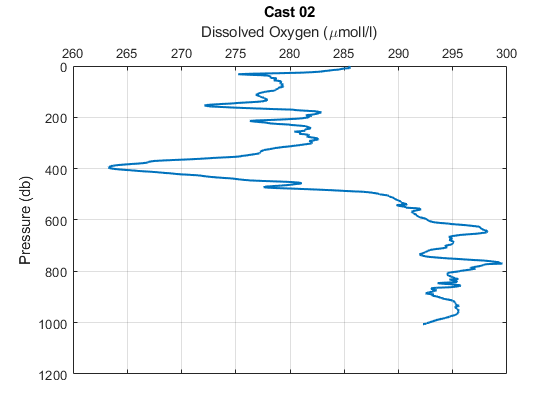

figure
plot(cast02.sbeox0mL_L*44.661,cast02.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 02')

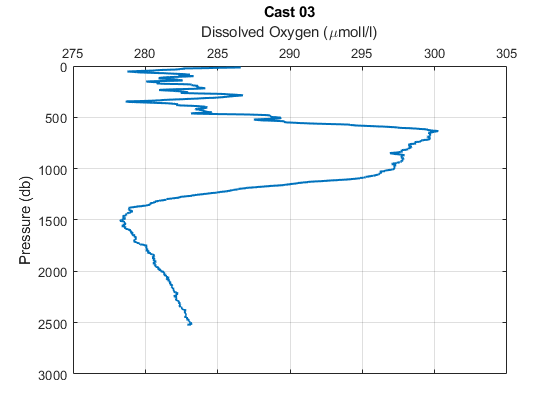


figure
plot(cast03.sbeox0mL_L*44.661,cast03.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 03')

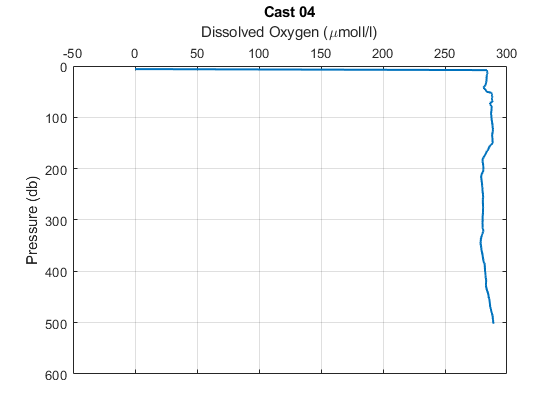


figure
plot(cast04.sbeox0mL_L*44.661,cast04.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 04')

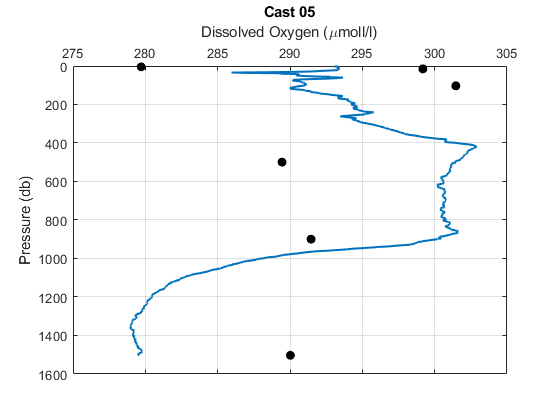


figure
plot(cast05.sbeox0mL_L*44.661,cast05.pm,'Linewidth',1.5)
hold on
plot(btlsum05.Winkler_mLL*44.661,btlsum05.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 05')

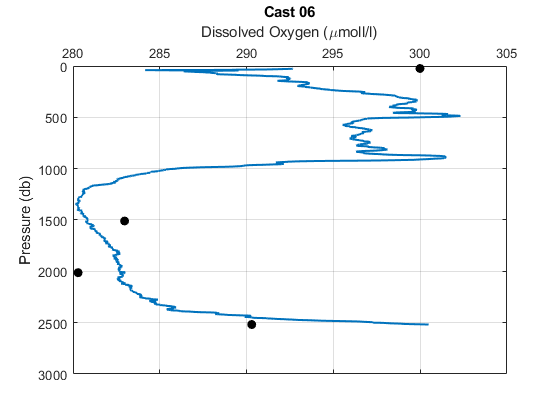


figure
plot(cast06.sbeox0mL_L*44.661,cast06.pm,'Linewidth',1.5)
hold on
plot(btlsum06.Winkler_mLL*44.661,btlsum06.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 06')

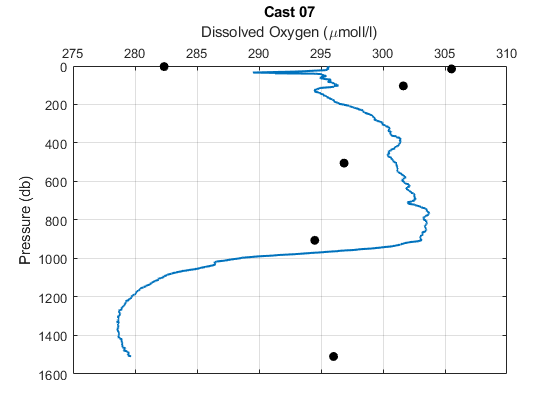


figure
plot(cast07.sbeox0mL_L*44.661,cast07.pm,'Linewidth',1.5)
hold on
plot(btlsum07.Winkler_mLL*44.661,btlsum07.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 07')

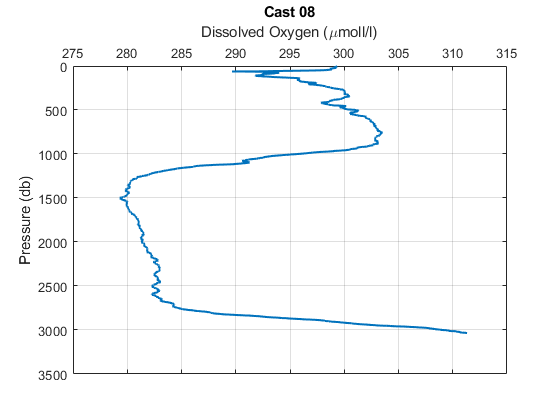


figure
plot(cast08.sbeox0mL_L*44.661,cast08.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 08')

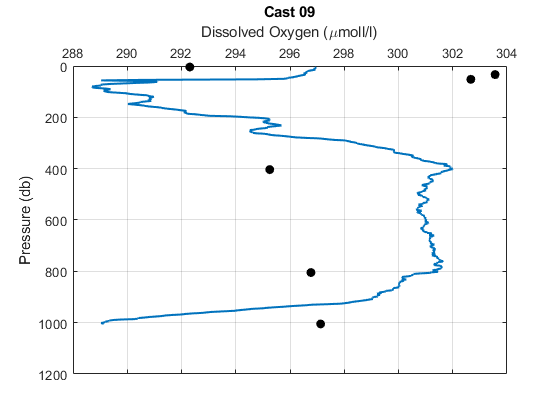


figure
plot(cast09.sbeox0mL_L*44.661,cast09.pm,'Linewidth',1.5)
hold on
plot(btlsum09.Winkler_mLL*44.661,btlsum09.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumoll/l)'); ylabel('Pressure (db)')
grid on
title('Cast 09')